# Limb Movement Classification with EMG Data: Statistical Features

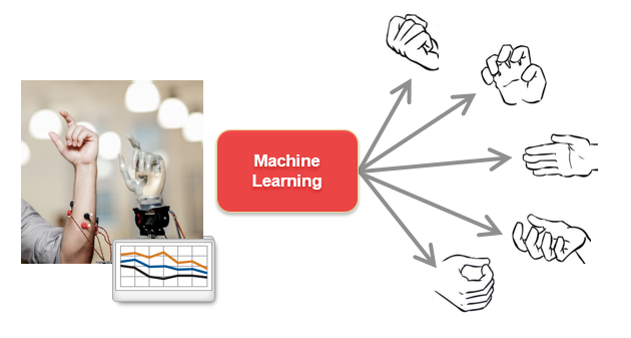

The goal of this analysis is to develop a classifier to identify type of movement from EMG signal for prosthetics development. We will process EMG sensor data with known actions, then train a classification algorithm to make predictions given new sensor readings.  

In this example, we will use basic statistical features as a first pass to see if this satisfies our accuracy requirements.

fs = 1800; % Sensor frequency (Hz)
dt = 1/fs; % Discrete time element (s)

## Import Data

First, we need to import the data from each of the different files into one table. A convenient way to do this is with `datastore`. [MATLAB datastore](https://www.mathworks.com/help/matlab/datastore.html) allow you to point at a collection of files, specify the formatting, and then read in all or a portion of the data as needed.

dataPath = pwd;
trainds = datastore(fullfile(pwd,'Data/TrainingData/*.csv'));
trainds.SelectedFormats{9} = '%C'; % Convert labels to categorical
preview(trainds)

Read all of the data into one table and create a time vector for plotting.

addpath(pwd,"Supervised_wStatisticalFeatures/")
TrainData = readall(trainds);
t = seconds(0:dt:dt*(height(TrainData)-1))';
TrainData.time = t

## Visualize Data

Visualize the signals, colored by action, in the [grouped scatter plot](https://www.mathworks.com/help/stats/gscatter.html) below.

sensorNum = 1;
gscatter(t,TrainData{:,sensorNum},TrainData.Action)
title("Sensor " + num2str(sensorNum) + " Raw Data")
xlabel('Time (sec)')
ylabel('Raw Sensor Data (\muV)')
legend(categories(TrainData.Action),'Location','EastOutside')

We can also use Live Tasks to interactively add a [`stackedplot`](matlab: web(fullfile(docroot, 'matlab/ref/stackedplot.html')))` to compare readings from the different sensors`.

h4 = stackedplot(TrainData,"XVariable","time");

% Add xlabel, and title
xlabel("time")
title("TrainData vs. time")

With clever indexing, we can choose for which motion to plot the data

actions = unique(TrainData.Action);
actionToPlot = actions(11);
stackedplot(TrainData{TrainData.Action == actionToPlot, 1:8},'DisplayLabels',"Sensor" + (1:8));
title(actionToPlot)

## Preprocess Data

Preprocessing can help the classification algorithms do a better job by smoothing, transforming, or applying statistics to the original signal that are better indicators of what is happening in the data. Examining the grouped scatter plot, it appears that the variance, range, and mean of small segments might help differentiate between classes.

We also need to consider the window length when calculating statistics. Rather than using moving statistics, we will take advantage of the fact that the recorded actions require a certain number of samples so all of those adjacent points are part of the same action. To figure out how big this block should be, we will take the greatest common divisor of the number of samples per action and the sampling frequency.

naction = mode(countcats(TrainData.Action)); % Samples in most common action
blocksize = naction/gcd(naction, fs);

## Feature Extraction Using Basic Statistics

Use `blockproc` to apply the functions to the blocks and then append the known action.

% Make functions and intelligent variable names
statfuns = @(x)[max(x) mean(x) min(x) var(x)];
varnames = strcat(repmat({'max';'mean';'min';'var'},8,1),repelem(cellstr(('1':num2str(8))'),numel({'max';'mean';'min';'var'}),1));

% Apply and append action
TrainDataStats = blockproc(TrainData{:,1:8},[blocksize 1],@(block)statfuns(block.data),"UseParallel",true);
TrainDataStats = array2table(TrainDataStats);
TrainDataStats.Properties.VariableNames = varnames;
TrainDataStats.Action = TrainData.Action(1:blocksize:end);

## Train Classifier

In order to train the classifier, we will use the Classification Learner App. This is an interactive environment where you can experiment with many different machine learning algorithms and evaluate how well they perform.

`classificationLearner`

We can use the generated code from the classification learner to calculate the validation accuracy.  In this case, we use a 25% holdout.

[trainedModel, validationAccuracy] = trainEMGClassifier(TrainDataStats);
disp(['Accuracy is ', num2str(validationAccuracy * 100) ,'%'])

## Make Predictions on Test Set

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.

Apply all of the same preprocessing steps to the new data.

testds = datastore(fullfile(strcat(dataPath,'/Data/TestingData/*.csv')));
testds.SelectedFormats{9} = '%C'; % Convert labels to categorical
TestData = readall(testds);
TestDataStats = preprocess(TestData)

Then make prediction and compare to known results.

[PredictedAction,score] = trainedModel.predictFcn(TestDataStats);

disp(['Accuracy is ', num2str(nnz(PredictedAction==TestDataStats.Action)./numel(PredictedAction)*100),'%'])
confusionchart(TestDataStats.Action, PredictedAction);
title("Predicted vs. True Class (counts)")

*Copyright 2025 The MathWorks, Inc.*